clc;
clear;

num_armax = [0.7555];
den_armax = [1 13.87 34.91];
k = 200.0;

% Closed-loop transfer function
tf_t_closed = tf(k * num_armax, den_armax);
tf_t_closed = feedback(tf_t_closed, 1)

tf_t_closed =
 
         151.1
  -------------------
  s^2 + 13.87 s + 186
 
Continuous-time transfer function.
Model Properties


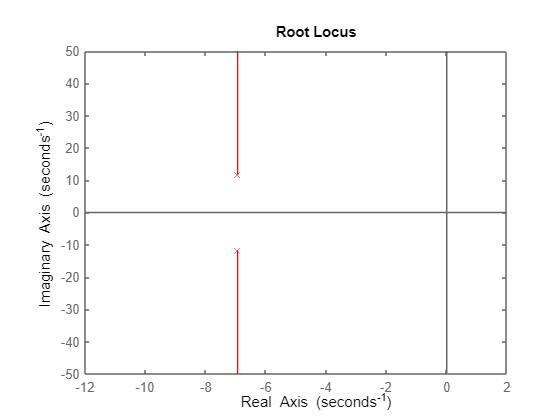


% Root locus
figure(1);
rlocus(tf_t_closed, 'r');

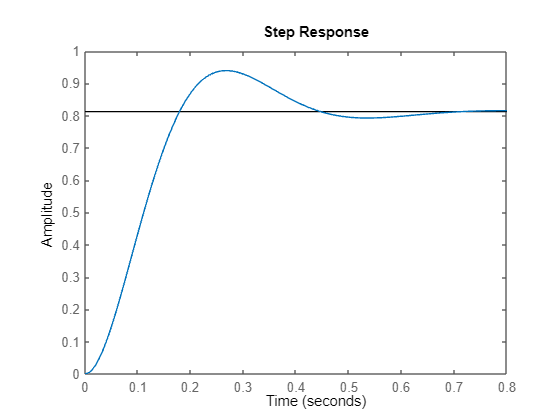

title('Root Locus');

% Step response
figure;
step_response = step(tf_t_closed);
t = linspace(0, 10, length(step_response)); % Generate time vector
step_info = stepinfo(tf_t_closed); % Get step response characteristics

% Plot step response
step(tf_t_closed);

title('Step Response');

% Damping ratio and natural frequency
[wn, zeta, poles] = damp(tf_t_closed)

wn =    13.6385
   13.6385


zeta =     0.5085
    0.5085


poles =   -6.9350 +11.7438i
  -6.9350 -11.7438i



% Steady-state value
steady_state_value = dcgain(tf_t_closed);

% Display results
disp('Step Response Characteristics:');

Step Response Characteristics:


disp(['Rise Time: ', num2str(step_info.RiseTime), ' sec']);

Rise Time: 0.12143 sec


disp(['Settling Time: ', num2str(step_info.SettlingTime), ' sec']);

Settling Time: 0.58539 sec


disp(['Overshoot: ', num2str(step_info.Overshoot), ' %']);

Overshoot: 15.637 %


disp(['Steady-State Value: ', num2str(steady_state_value)]);

Steady-State Value: 0.81232




num_armax = [0.006573  1.342];
den_armax = [1 12.47 29.84];
tf_t_open = tf(num_armax, den_armax)

tf_t_open =
 
   0.006573 s + 1.342
  ---------------------
  s^2 + 12.47 s + 29.84
 
Continuous-time transfer function.
Model Properties



k = 200.0;

% Closed-loop transfer function
tf_t_closed = tf(k * num_armax, den_armax);
tf_t_closed = feedback(tf_t_closed, 1)

tf_t_closed =
 
     1.315 s + 268.4
  ---------------------
  s^2 + 13.78 s + 298.2
 
Continuous-time transfer function.
Model Properties


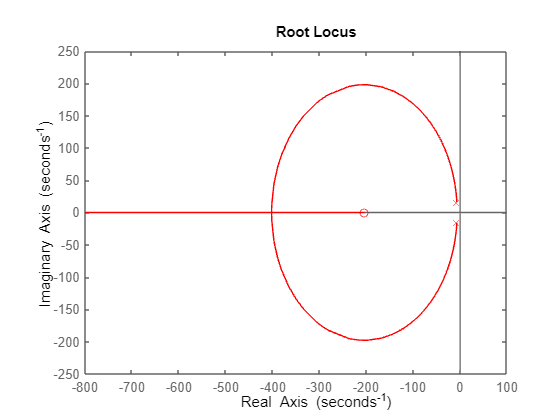


% Root locus
figure;
rlocus(tf_t_closed, 'r');

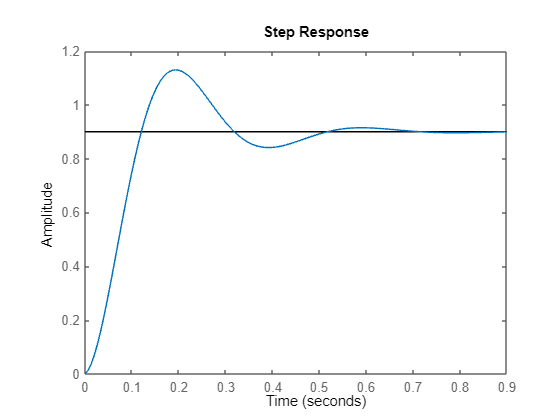

title('Root Locus');

% Step response
figure;
step_response = step(tf_t_closed);
t = linspace(0, 10, length(step_response)); % Generate time vector
step_info = stepinfo(tf_t_closed); % Get step response characteristics

% Plot step response
step(tf_t_closed);

title('Step Response');

% Damping ratio and natural frequency
[wn, zeta, poles] = damp(tf_t_closed)

wn =    17.2696
   17.2696


zeta =     0.3991
    0.3991


poles =   -6.8923 +15.8347i
  -6.8923 -15.8347i



% Steady-state value
steady_state_value = dcgain(tf_t_closed);

% Display results
disp('Step Response Characteristics:');

Step Response Characteristics:


disp(['Rise Time: ', num2str(step_info.RiseTime), ' sec']);

Rise Time: 0.084366 sec


disp(['Settling Time: ', num2str(step_info.SettlingTime), ' sec']);

Settling Time: 0.48202 sec


disp(['Overshoot: ', num2str(step_info.Overshoot), ' %']);

Overshoot: 25.5706 %


disp(['Steady-State Value: ', num2str(steady_state_value)]);

Steady-State Value: 0.89995
